close all;
clear all;

This script reads a set of CSV measurement and determines the average peak and the deviation for each measurement in the set. 

For reading a single measurement, see V1.

For reading the difference between two datasets, see V3

mes = "";

%Choose measurement set
%set = "20thApril\"; n = 8;
%set = "8thApril\";   n = 8;
%set = "5thApril\";  n = 5;
set = "29thApril\"; n = 6; mes = "\Meas3";

%Choose an antenna
%folder = "1814";
folder = "1937";
%folder = "2028";

The first part of this code reads the specified amount of measurements from a source folder and plots all in a graph.

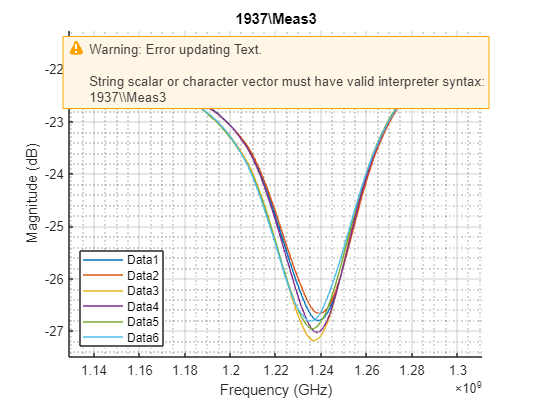

path = "C:\Users\guusb\OneDrive - Office 365 Fontys\Graduation project (Guus 2022)\TestResults\";

for ind = 1:2:(n*2-1)
    str = string(ceil(ind/2));
    filepath = append(path, set, folder,mes,"\TRACE0",str,".CSV");
   
    data = csvread(filepath, 3, 0)';  %the arguments are at which point the data starts
    data(3,:) = [];
    
    combinationMatrix(ind,:) = data(1,:); %this line could be redundant
    combinationMatrix(ind+1,:) = data(2,:);
end

tit = append(folder,mes);

%finds the extremes of the dataset to adjust the graph boundaries
ymax = max(data(2,:));
ymin = min(data(2,:));
xlim = [data(1,1) data(1,end)];
ylim = [ymin ymax];
    
figure()
hold on
for ind1 = 1:2:(n*2-1)
    plot(combinationMatrix(ind1,:), combinationMatrix(ind1+1,:));
end

axis([xlim ylim])
axis padded
grid on
grid minor;
title(tit);
xlabel("Frequency (GHz)");
ylabel("Magnitude (dB)");
hold on

%legend('show')
legend({'Data1','Data2','Data3','Data4','Data5','Data6','Data7','Data8'}, 'Location','southwest');

From this part the graphs are analysed to calculate the average peak frequency and the deviation of each data set from this frequency.

%readjust range to focus on the relevant peak
%trim_str = find(data(1,:)>900000000)-1;
%trim_str = trim_str(1,1);
%trim_end = find(data(1,:)>1300000000)-1;
%trim_end = trim_end(1,1);
trim_str = 1;
trim_end = 1001;

peak_array = zeros(1,n);
for indx = 1:2:(n*2-1)
    measurement = ceil(indx/2);
    ymin = min(combinationMatrix(indx+1,trim_str:trim_end));

    fmin = islocalmin(combinationMatrix(indx+1,trim_str:trim_end),'MinProminence',4); %finds the index of the peak
    xpeak = find(fmin);    %connects that index to the frequency value
    xpeak = xpeak+trim_str;

    fprintf("dataset %i: ",measurement);
    a = isempty(xpeak);
    
    if a < 1
        frez = combinationMatrix(indx,xpeak);
        fprintf("Resonance at %.2f MHz at %.1f dB.\n",frez/1000000,ymin);
        peak_array(1,measurement) = frez;
    else
        fprintf("No peak found within parameters.\n");
    end
end

dataset 1: 

Resonance at 1239.04 MHz at -26.8 dB.


dataset 2: 

Resonance at 1239.84 MHz at -26.7 dB.


dataset 3: 

Resonance at 1236.80 MHz at -27.2 dB.


dataset 4: 

Resonance at 1238.24 MHz at -27.0 dB.


dataset 5: 

Resonance at 1236.48 MHz at -27.0 dB.


dataset 6: 

Resonance at 1235.84 MHz at -26.8 dB.



fprintf("\n \n");

peak_mean = mean(peak_array);

diff_array = zeros(1,n);
for i = 1:n
    diff_array(i)=abs(peak_array(i)-peak_mean)/100000;
end
dev = mean(diff_array);
dev_perc = ((dev*1000000)/peak_mean)*100;

fprintf("Average peak is: %.2f MHz with a deviation of %.3f MHz, or %.2f %% \n",peak_mean/1000000,dev,dev_perc);

Average peak is: 1237.71 MHz with a deviation of 13.333 MHz, or 1.08 % 


% 
% for indx = 1:2:9
%     measurement = ceil(indx/2);
% 
%     fmin = islocalmin(combinationMatrix(indx+1,:),'MinProminence',15); %finds the index of the peak
%     xpeak = find(fmin);                                     %connects that index to the frequency value
%     if xpeak > 0
%         frez = combinationMatrix(indx,xpeak);                  %converts the frequency to MHz
%         %fprintf("Resonance at %.2f MHz at %.1f dB.\n",frez/1000000,ymin)
%         frez_string = string(frez/1000000);
%         ymin_string = string(ymin);
%         p = append("Resonance at ",frez_string, " MHz at ", ymin_string, "dB");
% 
%         precsion = 15;
%         peakrange= combinationMatrix(indx:indx+1,xpeak-precsion:xpeak+precsion);
% 
% 
%         %interpolate the peak to calculate peak -3dB
%         steps = (peakrange(1,end)-peakrange(1,1))/200;
%         finescale = peakrange(1,1):steps:peakrange(1,end); %create finer scale with same boundaries
% 
%         interpol = interp1(peakrange(1,:),peakrange(2,:),finescale,'cubic');
%         %plot(peakrange(1,:),peakrange(2,:),'o',finescale,interpol,':.');
% 
%         interdata = [finescale;interpol]; %parse vectors together
% 
%         %determine full width at half maximum
%         halfmax = ymin+3;
%         halfy = find(interdata(2,:) < halfmax);      %find the range where the data is below the values
% 
% 
%         fullwidth = abs(interdata(1,halfy(1)) - interdata(1,halfy(end)));    %calcutate the frequency width
% 
%         %calculate the Q factor
%         Q = frez/fullwidth;
%         Q_val = string(Q);
%         l = append(p, " with ", "Q factor ",Q_val,".");
%     else
%         l= "No peak found within parameters.";
%     end
%     fprintf("For Measurement %d : %s \n",measurement,l)
% end